**Controlling Subplot Coloring**

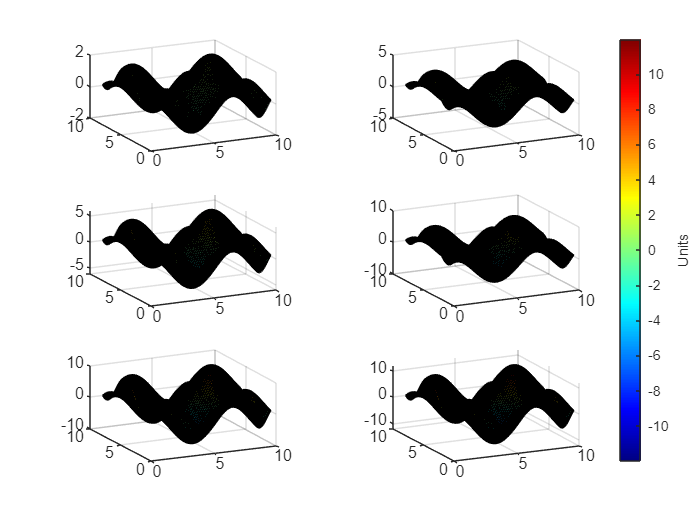

%% Controlling Subplot Coloring in MATLAB
% This script creates 6 3D subplots with a shared color scale and a single colorbar using the 'jet' colormap.

% First I Initialized the variables
c_fin = [0, 0]; % Initial color range
[X, Y] = meshgrid(1:0.1:10, 1:0.1:10); % Create grid for plotting

% Then I created a figure to hold it
figure; 
hold on;

% Nex I did a loop to generate 6 subplots but they all turned out to be not
% the color that I wanted 
for i = 1:6
    % Calculate Z values for the subplot
    Z(:, :, i) = i * (sin(X) + cos(Y));
    
    % Create subplot
    ax(i) = subplot(3, 2, i); 
    hold on; 
    grid on;
    
    % Create surface plot
    surf(X, Y, Z(:, :, i));
    
    % Set view angle and colormap
    view(-26, 30);
    colormap(ax(i), jet); % Apply the rainbow-like 'jet' colormap
    ca = caxis;
    c_fin = [min(c_fin(1), ca(1)), max(c_fin(2), ca(2))];
end

% Add a single colorbar to the figure
c = colorbar('eastoutside');
c.Label.String = 'Units';
set(c, 'Position', [0.9, 0.11, 0.03, 0.815]); % Adjust colorbar position

% Pause to ensure proper subplot resizing before scaling
pause(2);

% Adjust subplots for consistent color scale and resize them
for i = 1:6
    % Get the current position of the subplot
    pos = get(ax(i), 'Position');
    
    % Set subplot position and scale its color limits
    axes(ax(i));
    set(ax(i), 'Position', [pos(1), pos(2), 0.85 * pos(3), pos(4)]);
    set(ax(i), 'Clim', c_fin); % Synchronize color scale
end